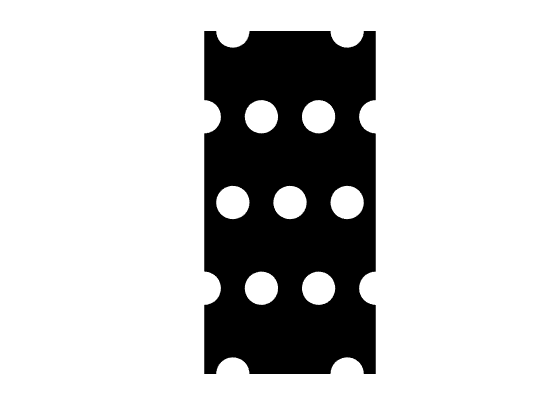

nelx=60;nely=120;volfrac=0.5;
%% LEVEL SET FUNCTION INITIALIZATION
r = min(nelx,nely)*0.1;%RADIUS OF INITIAL HOLES
hX = nelx*[repmat([1/6,5/6],1,3),repmat([0,1/3,2/3,1],1,2),1/2];
hY = nely*[kron([0,1/2,1],ones(1,2)),kron([1/4,3/4],ones(1,4)),1/2];
[X,Y] = meshgrid(0:1:nelx,0:1:nely);
dX = bsxfun(@minus,repmat(X,[1,1,numel(hX)]),reshape(hX,1,1,numel(hX)));
dY = bsxfun(@minus,repmat(Y,[1,1,numel(hY)]),reshape(hY,1,1,numel(hY)));
Phi = max(-3,min(3,min(sqrt(dX.^2+dY.^2)-r,[],3)));
pGpX = ([Phi(:,2:end) zeros(nely+1,1)] - [zeros(nely+1,1) Phi(:,1:end-1)]);
pGpY = ([Phi(2:end,:);zeros(1,nelx+1)] - [zeros(1,nelx+1); Phi(1:end-1,:)]);
gradPhi = sqrt((pGpX).^2+(pGpY).^2);
figure(1); contourf(Phi,[0,0]);
colormap([0,0,0]); set(gcf,'color','w'); axis equal; axis off;

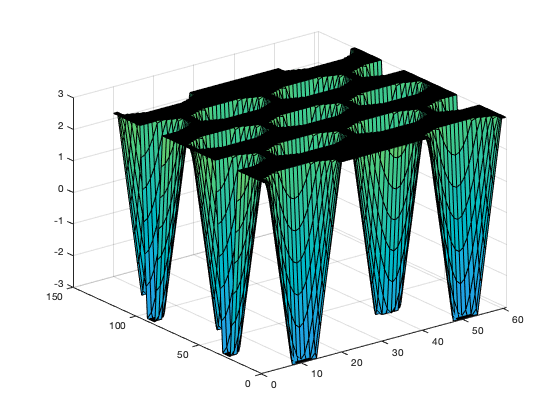

figure(2); surf(Phi); caxis([-12,12]);

No.1, Obj:24799907.820199, Vol:0.826732


No.2, Obj:24532587.866393, Vol:0.836561


No.3, Obj:24326112.507696, Vol:0.844885


No.4, Obj:24129421.172268, Vol:0.842203


No.5, Obj:24050368.427543, Vol:0.830376


No.6, Obj:24189623.457926, Vol:0.714526


No.7, Obj:23861230.447001, Vol:0.856775


No.8, Obj:24137063.690530, Vol:0.696533


No.9, Obj:23862121.114409, Vol:0.800824


No.10, Obj:23942957.411047, Vol:0.739732


No.11, Obj:23910231.895304, Vol:0.743714


No.12, Obj:23906830.083589, Vol:0.738858


No.13, Obj:23915361.839761, Vol:0.729730


No.14, Obj:23932886.274905, Vol:0.717975


No.15, Obj:23953689.532388, Vol:0.707134


No.16, Obj:23971596.294174, Vol:0.698014


No.17, Obj:23997251.066215, Vol:0.687478


No.18, Obj:24022493.368557, Vol:0.677385


No.19, Obj:24051289.038487, Vol:0.666929


No.20, Obj:24085696.768778, Vol:0.656396


No.21, Obj:24108760.165508, Vol:0.647169


No.22, Obj:24141063.165497, Vol:0.637113


No.23, Obj:24176801.455969, Vol:0.627002


No.24, Obj:24213068.419036, Vol:0.617164


No.25, Obj:24251592.901560, Vol:0.607196


No.26, Obj:24292314.783639, Vol:0.597239


No.27, Obj:24334988.681785, Vol:0.587467


No.28, Obj:24378209.317682, Vol:0.578032


No.29, Obj:24423422.156985, Vol:0.568842


No.30, Obj:24472811.419634, Vol:0.559254


No.31, Obj:24522456.683403, Vol:0.549983


No.32, Obj:24569719.876304, Vol:0.541561


No.33, Obj:24617178.840733, Vol:0.533302


No.34, Obj:24668771.185896, Vol:0.525256


No.35, Obj:24714445.986827, Vol:0.517321


No.36, Obj:24756248.843240, Vol:0.510640


No.37, Obj:24793104.794706, Vol:0.504936


No.38, Obj:24825999.091875, Vol:0.499910


No.39, Obj:24853611.139461, Vol:0.495555


No.40, Obj:24875316.760915, Vol:0.492131


No.41, Obj:24893514.323389, Vol:0.489334


No.42, Obj:24908080.864639, Vol:0.487057


No.43, Obj:24920364.139184, Vol:0.485120


No.44, Obj:24928605.727744, Vol:0.483921


No.45, Obj:24934980.324663, Vol:0.482913


No.46, Obj:24941424.312685, Vol:0.482075


No.47, Obj:24946142.136332, Vol:0.481556


No.48, Obj:24947112.551175, Vol:0.481471


No.49, Obj:24950424.639598, Vol:0.481563


No.50, Obj:24946127.047934, Vol:0.482572


No.51, Obj:24954772.467462, Vol:0.483651


No.52, Obj:24934841.341220, Vol:0.485369


No.53, Obj:24907066.483432, Vol:0.487586


No.54, Obj:24881073.652150, Vol:0.490162


No.55, Obj:24860341.991715, Vol:0.492394


No.56, Obj:24844307.379171, Vol:0.494177


No.57, Obj:24828281.915680, Vol:0.496010


No.58, Obj:24816224.986724, Vol:0.497401


No.59, Obj:24803710.644367, Vol:0.498904


No.60, Obj:24792886.756831, Vol:0.500229


No.61, Obj:24784221.233765, Vol:0.501306


No.62, Obj:24775988.119713, Vol:0.502339


No.63, Obj:24768927.021864, Vol:0.503233


No.64, Obj:24763696.883108, Vol:0.503859


No.65, Obj:24760247.924311, Vol:0.504240


No.66, Obj:24757997.789924, Vol:0.504466


No.67, Obj:24757744.296432, Vol:0.504402


No.68, Obj:24759322.253192, Vol:0.504070


No.69, Obj:24762289.406548, Vol:0.503563


No.70, Obj:24765747.764124, Vol:0.503002


No.71, Obj:24769925.664682, Vol:0.502339


No.72, Obj:24774423.809941, Vol:0.501636


No.73, Obj:24781139.543665, Vol:0.500635


No.74, Obj:24787198.023568, Vol:0.499734


No.75, Obj:24792857.989516, Vol:0.498900


No.76, Obj:24795689.139509, Vol:0.498442


No.77, Obj:24796920.743664, Vol:0.498202


No.78, Obj:24797565.416694, Vol:0.498048


No.79, Obj:24796525.357644, Vol:0.498150


No.80, Obj:24795908.906222, Vol:0.498171


No.81, Obj:24793671.038755, Vol:0.498416


No.82, Obj:24792709.258145, Vol:0.498484


No.83, Obj:24789992.978653, Vol:0.498787


No.84, Obj:24787745.264509, Vol:0.499047


No.85, Obj:24785243.588280, Vol:0.499330


No.86, Obj:24782847.865521, Vol:0.499604


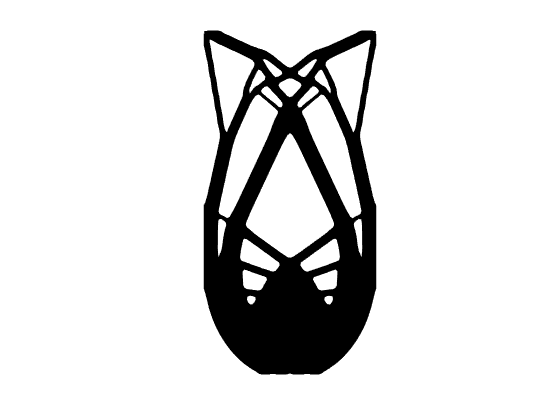

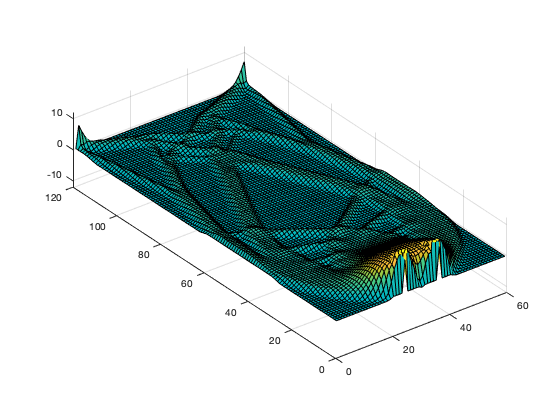

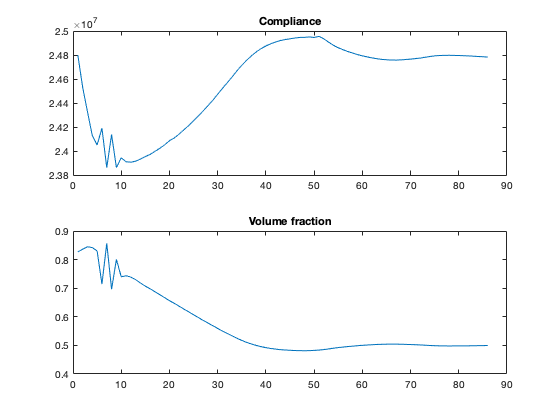

%% RADIAL BASIS FUNCTION INITIALIZATION
nNode = (nely+1)*(nelx+1);
Boundary = setdiff(unique([1:1:nely+1, nNode-nely:1:nNode, ...
    nely+1:nely+1:nNode, 1:nely+1:nNode-nely]), ...
    [(nely+1),nNode,0.4*nelx*(nely+1)+1,0.6*nelx*(nely+1)+1]);
Phi(Boundary)=-1e-9;
Alpha = Phi(:);
Phi = reshape(Alpha,nely+1,nelx+1);
%% FINITE ELEMENT ANALYSIS PREPARATION
E0 = 1; Emin = 1e-9; nu = 0.3; %MATERIAL PROPERTIES
A11 = [12 3 -6 -3; 3 12 3 0; -6 3 12 -3; -3 0 -3 12];
A12 = [-6 -3 0 3; -3 -6 -3 -6; 0 -3 -6 3; 3 -6 3 -6];
B11 = [-4 3 -2 9; 3 -4 -9 4; -2 -9 -4 -3; 9 4 -3 -4];
B12 = [ 2 -3 4 -9; -3 2 9 -2; 4 9 2 3; -9 -2 3 2];
KE = 1/(1-nu^2)/24*([A11 A12;A12' A11]+nu*[B11 B12;B12' B11]);
eleN1 = repmat((1:nely)',1,nelx)+kron(0:nelx-1,(nely+1)*ones(nely,1));
eleNode = repmat(eleN1(:),1,4)+repmat([0,nely+[1,2],1],nelx*nely,1);
edofMat = kron(eleNode,[2,2])+repmat([-1,0],nelx*nely,4);
iK = reshape(kron(edofMat,ones(8,1))',64*nelx*nely,1);
jK = reshape(kron(edofMat,ones(1,8))',64*nelx*nely,1);
%% BOUNDARY CONDITION DEFINITION
F = sparse([2*(nely+1)-1,2*nNode-1],[1,1],[-100,-100],2*nNode,1);
fixeddofs = [2*0.4*nelx*(nely+1)+1,2*0.4*nelx*(nely+1)+2, ...
    2*0.6*nelx*(nely+1)+1,2*0.6*nelx*(nely+1)+2];
freedofs = setdiff(1:2*nNode,fixeddofs);
U = zeros(2*nNode,1);
%% ITERATION OPTIMIZATION
nLoop = 500; nRelax = 30;
dt = 0.1; delta = 10; mu = 20; gamma = 0.05;
comp = zeros(nLoop,1); vol = zeros(nLoop,1);
for iT = 1:nLoop
    %% FINITE ELEMENT ANALYSIS
        [s,t] = meshgrid(-1:0.1:1,-1:0.1:1);
    tmpPhi = (1-s(:)).*(1-t(:))/4*Phi(eleNode(:,1))'+(1+s(:)).*(1-t(:))/4*...
        Phi(eleNode(:,2))'+(1+s(:)).*(1+t(:))/4*Phi(eleNode(:,3))'+...
        (1-s(:)).*(1+t(:))/4*Phi(eleNode(:,4))';
    eleVol = sum(tmpPhi>=0,1)'/numel(s);
    vol(iT) = sum(eleVol)/(nelx*nely);
    sK = reshape(KE(:)*(Emin+eleVol'*(E0-Emin)),64*nelx*nely,1);
    K = sparse(iK,jK,sK); K = (K+K')/2;
    U(freedofs,1) = K(freedofs,freedofs)\F(freedofs,1);
    eleComp = sum((U(edofMat)*KE).*U(edofMat),2).*(Emin+eleVol*(E0-Emin));
    comp(iT) = sum(eleComp);
    %% DISPLAY RESULTS
    fprintf('No.%i, Obj:%f, Vol:%f\n',[iT,comp(iT),vol(iT)]);
    figure(3); contourf(Phi,[0,0]);
    colormap([0,0,0]); set(gcf,'color','w'); axis equal; axis off;
    %saveas(gcf,sprintf('Optim_pictures/%i.png', iT));
    figure(4); surf(Phi); caxis([-12,12]);
    axis equal; axis([0,nelx,0,nely,-12,12]); view(3);
    figure(5);  subplot(2,1,1); plot(comp(1:iT),'-'); title('Compliance');
                subplot(2,1,2); plot(vol(1:iT),'-'); title('Volume fraction');
    %% CONVERGENCE CHECK
    if iT>nRelax && abs(vol(iT)-volfrac)/volfrac<1e-3 && ...
        all(abs(comp(iT)-comp(iT-9:iT-1))/comp(iT)<1e-3)
        break;
    end
    %% LAGRANGE MULTIPLIER
    if iT<=nRelax
        lag = mu*(vol(iT)-vol(1)+(vol(1)-volfrac)*iT/nRelax);
    else
        lag = lag+gamma*(vol(iT)-volfrac);
        gamma = min(gamma+0.05,5);
    end
    %% LEVEL SET FUNCTION EVOLUTION
    pGpX = ([Phi(:,2:end) zeros(nely+1,1)] - [zeros(nely+1,1) Phi(:,1:end-1)]);
    pGpY = ([Phi(2:end,:);zeros(1,nelx+1)] - [zeros(1,nelx+1); Phi(1:end-1,:)]);
    gradPhi = sqrt((pGpX).^2+(pGpY).^2);
    indexDelta = (abs(Phi(:))<=delta);
    DeltaPhi = zeros(size(Phi));
    DeltaPhi(indexDelta) = 0.75/delta*(1-Phi(indexDelta).^2/delta^2);
    eleComp = reshape(eleComp,nely,nelx);
    eleCompLR = [eleComp(:,1),eleComp]+[eleComp,eleComp(:,end)];
    nodeComp = ([eleCompLR;eleCompLR(end,:)]+[eleCompLR(1,:);eleCompLR])/4;
    B = (nodeComp(:)/median(nodeComp(:))-lag).*DeltaPhi(:)*delta/0.75;
    Alpha = Alpha+dt*B;
    Alpha = Alpha/mean(gradPhi(unique(eleNode((eleVol<1 & eleVol>0),:))));%broke the program when the body is solid, but prevent oscilations
    Phi = reshape(Alpha,nely+1,nelx+1);
    Phi(Boundary)=min(Phi(Boundary),-1e-9);
end